# Simple selection equation

As derived in the experiment hangout for two populations with counts $N_1$ and $N_2$ respectively, and proportions $p \equiv N_1 / (N_1 + N_2)$ and $q \equiv 1 - p$ respectively, the change of these proportions is given by


$$\Delta p_{i \rightarrow i+i} = \frac{p_i q_i s}{1 - q_i s},$$


where the subindex indicates the generation at which is being calculated and $s \in [0, 1]$ is the selection coefficient that tells us *how much less fit is population *$N_2$ *with respect to *$N_1$.

As an exercise we will plot how the proportion changes over generations for different values of the selection coefficient assuming equal initial proportions $p_o = q_o = 0.5$.

We start by defining the variables that we are going to need

% Define initial proportions
po = 0.5;
qo = 1 - po;

% Define the series of selection coefficients we will test
s_array = [0.05 0.1 0.25];

% Define the number of generations to run the simulation
n_gen = 100;

Now we initialize the arrays to save the proportions and loop through the number of generations for each selection coefficient. We will use the function discrete_selection that we defined for this purposes.

% Initialize array to save the multiple results
p_mat = zeros(length(s_array), n_gen+1);
for j=1:length(s_array)
    p_mat(j, 1:end) = discrete_selection(po, s_array(j), n_gen);
end

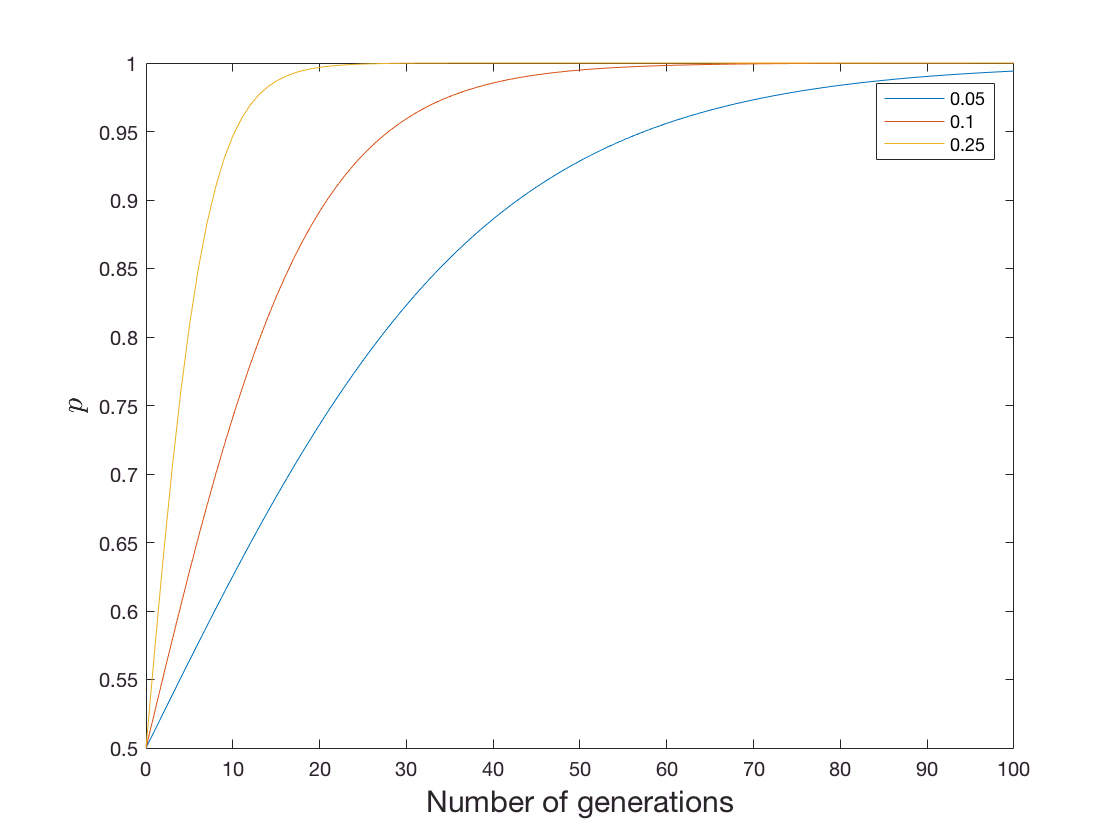

plot(0:n_gen, p_mat)
xlabel('Number of generations', 'Fontsize', 15)
ylabel('$p$','Interpreter','LaTex','FontSize',15)
legend('0.05', '0.1', '0.25')